%W1 
%P2
clear
format long
syms x;

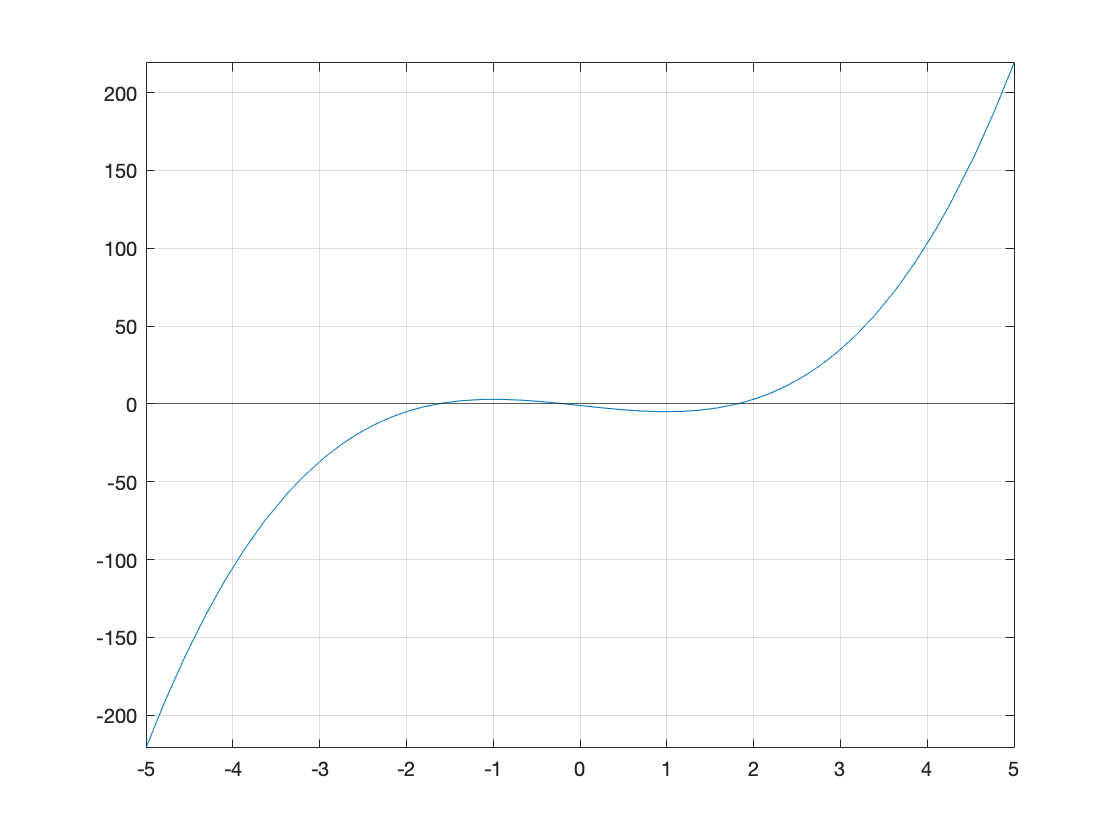

%a
f(x) = 2*x^3 -6*x - 1;
fplot(f)
grid on;
yline(0);

x0 = bisec(f, -2, -1, 5*10^-8);
x1 = bisec(f, -1, -0, 5*10^-8);
x2 = bisec(f, 1, 2, 5*10^-8);
round(x0,7)

ans =   -1.641783500000000


round(x1,7)

ans =   -0.168254400000000


round(x2,7)

ans =    1.810037900000000


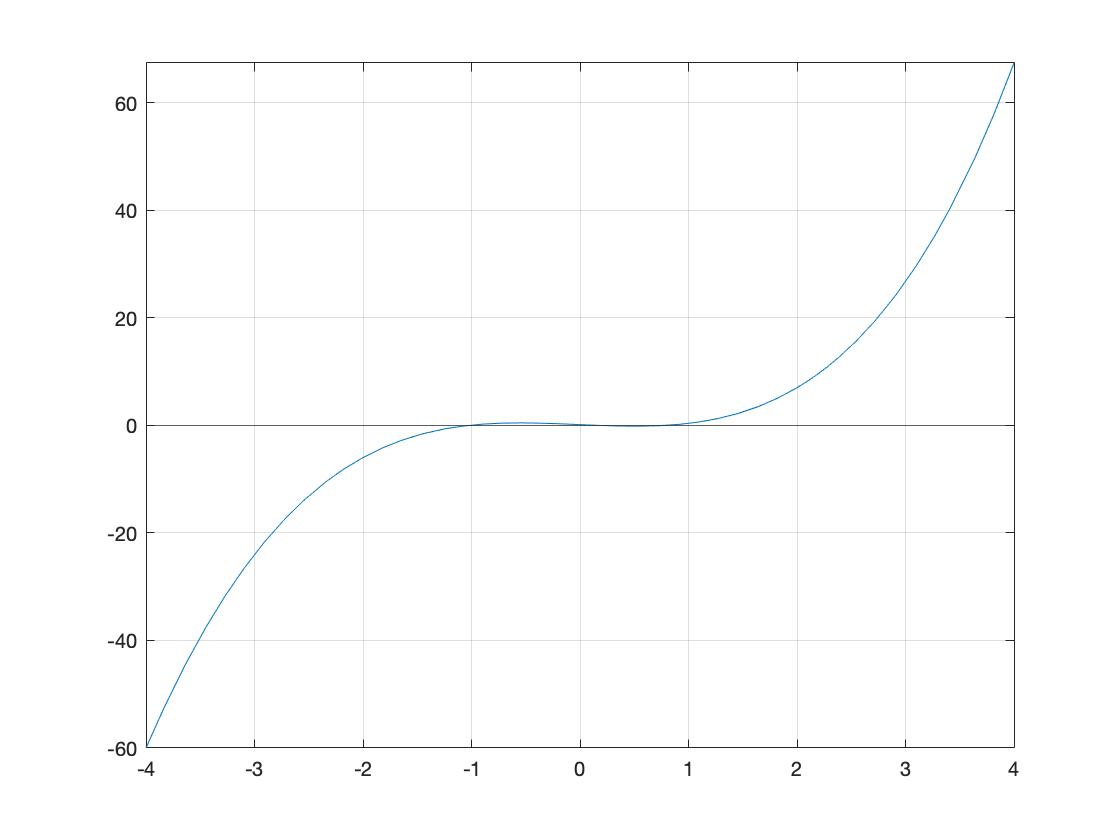

%b
f(x) = exp(x-2) + x^3 - x;
fplot(f)
grid on;
yline(0);
xlim([-4 4]);

x0 = bisec(f, -1.5, -0.5, 5*10^-8);
x1 = bisec(f, -0.5, 0.5, 5*10^-8);
x2 = bisec(f, 0.5, 1.5, 5*10^-8);
round(x0,7)

ans =   -1.023482100000000


round(x1,7)

ans =    0.163822200000000


round(x2,7)

ans =    0.788941400000000


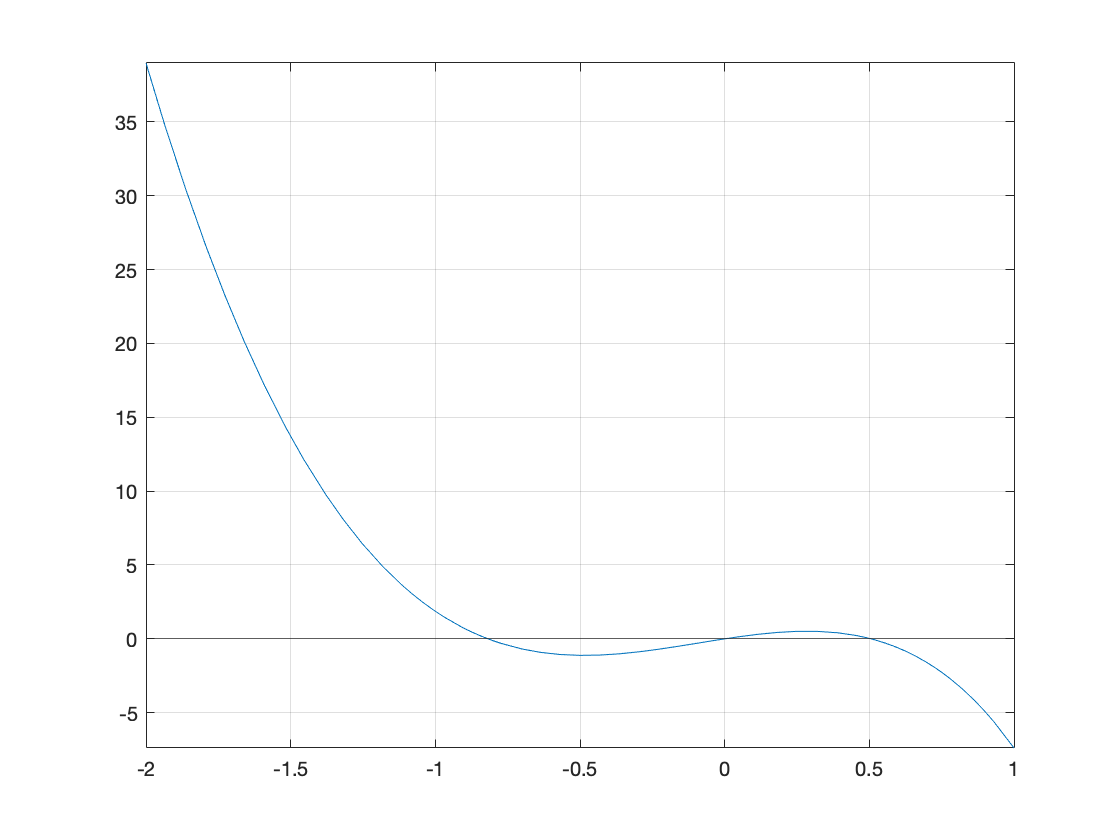

%c
f(x) = 1 + 5*x -6*x^3 -exp(2*x);
fplot(f)
grid on;
yline(0);
xlim([-2 1]);

x0 = bisec(f, -1.5, -0.5, 5*10^-8);
x1 = bisec(f, -0.5, 0.5, 5*10^-8);
x2 = bisec(f, 0.5, 1.5, 5*10^-8);
round(x0,7)

ans =   -0.818093700000000


round(x1,7)

ans =      0


round(x2,7)

ans =    0.506308300000000


%P3
%a 
% x^3 = 2x + 2 => x = (2x+2)^(1/3)
f(x) = (2*x+2)^(1/3);
x0 = fixpoint(f, 1, 10000, 10^-10);
round(x0, 9)

$$ans = 1.769292354$$

%b 
% exp(x) + x = 7
% x = log(7-x)
f(x) = log(7-x);
x0 = fixpoint(f, 1, 10000, 10^-10);
round(x0, 9)

$$ans = 1.672821699$$

%(c) exp(x) + sin x = 4
% x = log(4 - sin(x))
f(x) = log(4-sin(x));
x0 = fixpoint(f, 1, 10000, 10^-10);
round(x0, 9)

$$ans = 1.129980499$$

%P4
%b
%f(x) = 2*x^3 -6*x - 1;
%f(x) = exp(x-2) + x^3 - x;
%f(x) = 1 + 5*x -6*x^3 -exp(2*x);
%f(x) = x^3 - 2*x - 2;
%f(x) = exp(x) + x -7;
f(x) = exp(x) + sin(x) - 4;
x0 = newton(f, 0, 10^-10);
round(x0, 9)

$$ans = 1.129980499$$

%P5
A = [3,-1,0,0,0,1/2;
    -1,3,-1,0,1/2,0;
    0,-1,3,-1,0,0;
    0,0,-1,3,-1,0;
    0,1/2,0,-1,3,-1;
    1/2,0,0,0,-1,3];
b = [5/2; 3/2; 1; 1; 3/2; 5/2];
x0 = rand(length(b), 1)

x0 =    0.814723686393179
   0.905791937075619
   0.126986816293506
   0.913375856139019
   0.632359246225410
   0.097540404999410


x0 = jacob(A, b, x0, 1e5);
x0

x0 =      1
     1
     1
     1
     1
     1


Function

function [result] = bisec(f, a, b, tol)
% a b is the search range [a,b]
% f(x) is the function
% tol is tolerance error
result = Inf;
if (f(a)*f(b) < 0)
    while ((b-a)/2 > tol)
        c = (a + b)/2;
        if f(c) == 0
            result = c;
            break
        end
        
        if (f(a) * f(c)<0)
            b = c;
        else 
            a = c;
        end
    end
    result = c;
end
end

% Fix point iteration
function [result] = fixpoint(f, x0, N, tol)
result = x0;
for i = 1:N
    result = f(result);
    if (abs(result - f(result)) < tol)
        break
    end
end
end

% Newton method
function [result] = newton(f, x0, tol)
D = diff(f);
result = x0;
x1 = result - f(result)/D(result);
e = x1 - x0;

while (abs(e) > tol)
    e = - f(result)/D(result);
    result  = result - f(result)/D(result);
end
end

% Jacobian method
function [result] = jacob(A, b, x0, k)
n=length(b);     
D=diag(diag(A));        
r=A-D;      
x=x0.*ones(n,1);
for j=1:k
  x=D\(b-r*x);
end    
result = x;
end